clc 
clear
addpath("Functions\")
yalmip('clear')

**State Space formulation and discretization**

syms beta(t) tau w
linBeta = 0;%% Starh with beta at 0 degrees linearization
winDir = deg2rad(90);
muWind = 1.5;
[A_cont,B_cont] = Linearization_Wind(linBeta,beta,tau,winDir,w,muWind); 
% 
 C_cont=[1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
         0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
         0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0;
         0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0;
         0 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0;
         0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0;
         0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0;
         0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0;]

C_cont =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0



D =0;


l=18;

h = 0.2; % Discrete time step,
[A,B,C] = Forward_BackEuler(A_cont,B_cont,C_cont,h)

A =     1.0000         0         0    0.0150    0.0000         0         0         0    0.1984   -0.0000    0.0000    0.0015    0.0000         0         0         0    0.0000
         0    1.0000         0   -0.0001    0.0002         0         0         0   -0.0000    0.1984    0.0000   -0.0000    0.0000         0         0         0    0.0000
         0         0    1.0000    0.0003   -0.0000         0         0         0   -0.0000    0.0000    0.1982   -0.0001   -0.0000         0         0         0   -0.0000
         0         0         0    0.9980    0.0001         0         0         0    0.0001   -0.0000   -0.0000    0.1997    0.0000         0         0         0    0.0000
         0         0         0   -0.9691    0.9999         0         0         0   -0.0000   -0.0033    0.0000   -0.0969    0.1850         0         0         0    0.0129
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    0.2000 

B = 1.0e-03 *

    0.0075    0.0000   -0.0000    0.0000    0.0075    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0075    0.0000    0.0000    0.0000    0.0075    0.0000
    0.0000    0.0043    0.0000    0.0043    0.0000    0.0043    0.0000    0.0043
   -0.0004   -0.0000   -0.0000   -0.0000   -0.0004   -0.0000   -0.0000   -0.0000
    0.0002    0.0000   -0.0390    0.0000    0.0002    0.0000   -0.0390    0.0000
         0    0.0001         0         0         0   -0.0001         0         0
         0         0         0    0.0001         0         0         0   -0.0001
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0751    0.0003   -0.0000    0.0003    0.0751    0.0003   -0.0000    0.0003
    0.0000    0.0000    0.0751    0.0000    0.0000    0.0000    0.0751    0.0000


C =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0



sys = ss(A,B,C,D);
n = length(A);

simTime = 60/h;

**Wind Paramaters**



ti = 0.05; %turbulence itencity

CV = ti*muWind;

 
%Turbulent part
Wt= zeros(1,simTime);
wp = (muWind*pi)/(2*340.2);
at = exp(-wp*h)

at = 0.9986

stdt= (ti *muWind*sqrt(1-at^2));

%Slow Part
q = 2^2/600 ; %slow part changinf by 2m/s over 10 min.
stdw = sqrt(h*q);
Ws= zeros(1,simTime);
Ws(50) = 1.5;


W = zeros(1,simTime)

W =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


**MPC Formulation**


ref =0;
Hp = 30;
Hu = 1;
%Lifting the dynamics to be expressed in terms of delta u.
[ALift, BuLift, BduLift, Psi, Upsilon_B, Theta] = MPCLift(A, B, C ,Hp, Hu)

Condition of:
 Psi: Inf
 Upsilon: 77441896101194064.000000 
 Theta: 77441896101194064.000000

ALift =     1.0000         0         0    0.0150    0.0000         0         0         0    0.1984   -0.0000    0.0000    0.0015    0.0000         0         0         0    0.0000
         0    1.0000         0   -0.0001    0.0002         0         0         0   -0.0000    0.1984    0.0000   -0.0000    0.0000         0         0         0    0.0000
         0         0    1.0000    0.0003   -0.0000         0         0         0   -0.0000    0.0000    0.1982   -0.0001   -0.0000         0         0         0   -0.0000
         0         0         0    0.9980    0.0001         0         0         0    0.0001   -0.0000   -0.0000    0.1997    0.0000         0         0         0    0.0000
         0         0         0   -0.9691    0.9999         0         0         0   -0.0000   -0.0033    0.0000   -0.0969    0.1850         0         0         0    0.0129
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0    0.2

BuLift =     0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000


BduLift =     0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000         0   -0.0000         0   -0.0000         0    0.0000         0
    0.0001    0.0000   -0.0000    0.0000    0.0001    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000


Psi =     1.0000         0         0    0.0150    0.0000         0         0         0    0.1984   -0.0000    0.0000    0.0015    0.0000         0         0         0    0.0000
         0    1.0000         0   -0.0001    0.0002         0         0         0   -0.0000    0.1984    0.0000   -0.0000    0.0000         0         0         0    0.0000
         0         0    1.0000    0.0003   -0.0000         0         0         0   -0.0000    0.0000    0.1982   -0.0001   -0.0000         0         0         0   -0.0000
         0         0         0    0.9980    0.0001         0         0         0    0.0001   -0.0000   -0.0000    0.1997    0.0000         0         0         0    0.0000
         0         0         0   -0.9691    0.9999         0         0         0   -0.0000   -0.0033    0.0000   -0.0969    0.1850         0         0         0    0.0129
         0         0         0   -9.6911   -0.0005         0         0         0   -0.0004   -0.0327    0.0000   -0.9686    0.8502         

Upsilon_B =     0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0004    0.0000    0.0000    0.0000   -0.0004    0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Theta =     0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0004    0.0000    0.0000    0.0000   -0.0004    0.0000
         0    0.0000         0         0         0   -0.0000         0         0
         0         0         0    0.0000         0         0         0   -0.0000
    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



p = size(B,2);
m = size(C,1)

m = 8



%Tune values from Q and R 
QLift = 100*eye(Hp*m);
RLift = 1*eye(Hu*p);
rho =ones(1,2);
rho(1) = 10000

rho =        10000           1


rho(2) = 1

rho =        10000           1





t = 1:1:simTime;
duPlot = zeros(p,simTime);
Xplant = zeros(n,simTime);
Yplant = zeros(n,simTime);
x = zeros(n,simTime);
u = zeros(p,simTime);


du = sdpvar(8*Hu,1);
slack = sdpvar(2,1);

 Tau = [ones(Hp*m,1)]

Tau =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



% for i=1:Hp
%     Tau((i-1)*m+1:i*m) = [0;0;15;0;0];
% end
constraints = [];
for i=1:Hp
    Tau((i-1)*m+1:i*(m)) = [0;0;15;0;0;0;0;0];
end
% Xplant(:,1) = [0 0 0 deg2rad(10) 0 0 0 0]';
Xplant(:,1) = [0 0 15 deg2rad(0) deg2rad(0) 0 0 0 0 0 0 0 0 0 0 0 1]';


noise = 1;  
f = waitbar(0,'Please wait...');
tic

lin_count = 0

lin_count = 0


for i=2:(simTime)
    % Calculate the Plant

    %Wind speed stuff
   
    if i > 50 && i <= 300

        et = normrnd(0,stdw);
        Ws(i) = Ws(i-1)+ et;

        es = normrnd(0,stdt^2);
        Wt(i) = at * Wt(i-1)+ es;

        W(i)  = Ws(i) + Wt(i);

        if W(i) <=0
            W(i) = 0;
        end
    end
    Xplant(17,i-1) = W(i);
    Xplant(:,i) = A * Xplant(:,i-1) + B*u(:,i-1);
    
    if abs(linBeta-Xplant(5,i))>deg2rad(20)
        lin_count= lin_count+1;
        waitbar(i/simTime,f, sprintf('New linearization point. Total: %i', lin_count));
       linBeta = Xplant(5,i);
       [A_cont,B_cont] = Linearization_Wind(linBeta,beta,tau,winDir,w,muWind); 
       [A,B,C] = Forward_BackEuler(A_cont,B_cont,C_cont,h);
       [ALift, BuLift, BduLift, Psi, Upsilon, Theta] = MPCLift(A, B, C ,Hp, Hu);
    end
    xopt = Xplant(:,i); % Seh the current state as the starting point for the optimization.
    % xopt = y0';

    z = Psi * xopt + Upsilon_B * u(:,i-1) + Theta * du;
    objective = ( (z - Tau)' * QLift * (z - Tau) + du' * RLift * du + rho * slack);
    %constraints = [abs(z(2:5:end)) <= deg2rad(5) + slack(1),abs(z(3:5:end))  <= deg2rad(1.5)+ slack(2) ,abs(u(:,i-1)+du(1:p))<= [100;100;100;100;100;100;100;100],slack >= 0]
    constraints = [abs(z(1:m:end)+l.*sin(z(4:m:end)).*cos(z(5:m:end))) <= 0.1 + slack(1),abs(z(2:m:end)+l.*sin(z(4:m:end)).*sin(z(5:m:end)))<=0.1 + slack(1),abs(u(:,i-1)+du(1:p))<= [200;200;200;200;200;200;200;200],slack >= 0]


    ops = sdpsettings('solver','ipopt');
    ops.verbose = 0;
    % ops.verbose = 0; % makes yalmip quiet
    optimize(constraints,objective, ops);

     % cvx_begin quiet
     %        variables du(Hu*p) slack(2)
     %        z = Psi * xopt + Upsilon_B * u(:,i-1)+ Upsilon_W * w(i) + Theta * du;
     %        minimize ( (z - Tau)' * QLift * (z - Tau) + du' * RLift * du + rho * slack.^2);
     %        subject to
     %             abs(u(:,i-1)+du(1:p)) <= [100;100;100;100;100;100;100;100];
     %             abs(z(2:5:end))  <= deg2rad(1) + slack(1);
     %             abs(z(3:5:end))  <= deg2rad(1.5)+ slack(2);
     %             slack >= 0;
     %        %    xopt(4)<=deg2rad(2);
     %   cvx_end 
     % 
    % 


    duPlot(:,i) = du(1:p);
    waitbar(i/simTime,f, sprintf('Simulating step: %i of %i',i, simTime));
    u(:,i) = u(:,i-1) + du(1:p);
end

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: 10006818189194689898517883011314221056.000000
 Upsilon: 52305988444813920.000000 
 Theta: 52305988444813920.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 141337934027693136.000000 
 Theta: 141337934027693136.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 35750622925696048.000000 
 Theta: 35750622925696048.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 51527816596626184.000000 
 Theta: 51527816596626184.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 112071575839909472.000000 
 Theta: 112071575839909472.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 188928537032189472.000000 
 Theta: 188928537032189472.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 76012663715631632.000000 
 Theta: 76012663715631632.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 298827991729375360.000000 
 Theta: 298827991729375360.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: 11533014358951990728217419259031060480.000000
 Upsilon: 86313086725749456.000000 
 Theta: 86313086725749456.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 104445781028967776.000000 
 Theta: 104445781028967776.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 101309057204281472.000000 
 Theta: 101309057204281472.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 59028415358669352.000000 
 Theta: 59028415358669352.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 208754576731419520.000000 
 Theta: 208754576731419520.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 20652621858511808.000000 
 Theta: 20652621858511808.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 87763230383394960.000000 
 Theta: 87763230383394960.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 100116806549977216.000000 
 Theta: 100116806549977216.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 121864685876478016.000000 
 Theta: 121864685876478016.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: 83693410944823398019424333516945489920.000000
 Upsilon: 128233589399495520.000000 
 Theta: 128233589399495520.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 150339088455138304.000000 
 Theta: 150339088455138304.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 139121725400854416.000000 
 Theta: 139121725400854416.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 99263114064990656.000000 
 Theta: 99263114064990656.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


Condition of:
 Psi: Inf
 Upsilon: 206468063185910912.000000 
 Theta: 206468063185910912.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


Condition of:
 Psi: Inf
 Upsilon: 90764439423587856.000000 
 Theta: 90764439423587856.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


Condition of:
 Psi: Inf
 Upsilon: 84386607632347856.000000 
 Theta: 84386607632347856.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


Condition of:
 Psi: Inf
 Upsilon: 75096436830955920.000000 
 Theta: 75096436830955920.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 59833782891972848.000000 
 Theta: 59833782891972848.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 111273488424282288.000000 
 Theta: 111273488424282288.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 83471429730006768.000000 
 Theta: 83471429730006768.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 85486350304389248.000000 
 Theta: 85486350304389248.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: 56809771252307379146308925473115078656.000000
 Upsilon: 257956446322218752.000000 
 Theta: 257956446322218752.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 298588137787480512.000000 
 Theta: 298588137787480512.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 217683201212329536.000000 
 Theta: 217683201212329536.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: 58879245319517655021227550589312827392.000000
 Upsilon: 504733138929639872.000000 
 Theta: 504733138929639872.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 96123157848748704.000000 
 Theta: 96123157848748704.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

Condition of:
 Psi: Inf
 Upsilon: 195901527450205984.000000 
 Theta: 195901527450205984.000000

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4|              Element-wise inequality 2x1|              1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                               Constraint|   Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #2|   Element-wise inequality (derived) 30x1|            0.1 to 1|
|   #3|    Element-wise inequality (derived) 8x1|            1 to 200|
|   #4

%close(bar)
toc

Elapsed time is 1388.986620 seconds.


delete(f)

**Ploting**

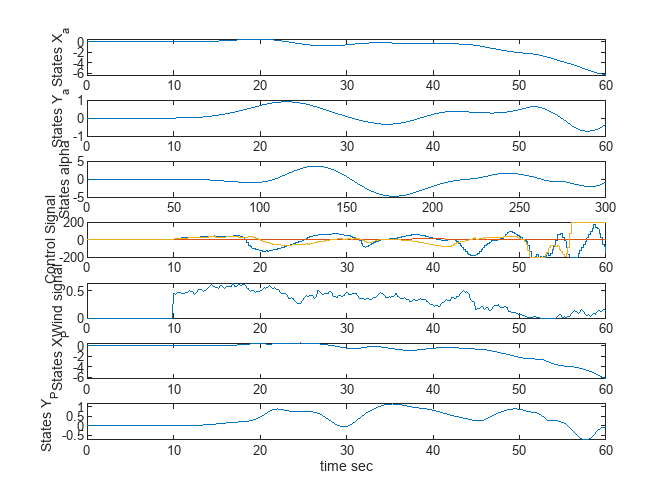

clf

Xplayload = Xplant(1,:) + l.*sin(Xplant(4,:)).*cos(Xplant(5,:));
Yplayload = Xplant(2,:) + l.*sin(Xplant(4,:)).*sin(Xplant(5,:));

t1 = linspace(0, 60, (60/h));


subplot(7,1,1)
plot(t1, Xplant(1,:));
ylabel("States X_a")
subplot(7,1,2)
plot(t1, Xplant(2,:));
ylabel("States Y_a")
subplot(7,1,3)
plot(t, rad2deg(Xplant(4,:)));
ylabel("States alpha")
subplot(7,1,4)
stairs(t1, u(1,:));
hold on
stairs(t1, u(2,:));
stairs(t1, u(3,:));
ylabel("Control Signal")
hold off
subplot(7,1,5)
plot(t1, W);
ylabel("Wind signal")
subplot(7,1,6)
plot(t1, Xplayload);
ylabel("States X_P")
subplot(7,1,7)
plot(t1, Yplayload);
ylabel("States Y_P")
xlabel("time sec")


% subplot(5,1,5)
% stairs(t, duPlot(1,:));
% ylabel("\Delta u")
% xlabel("Time")

%exportgraphics(gcf,'MPC_MoreWindSTatiorayPayload.pdf','ContentType','vector')

